## Kalman filter example

% Postupci su radjeni po ovim izvorima:
    % https://www.youtube.com/watch?v=UZsxFpjmdAs

### Ucitavanje podataka sa IMU senzora

%% Ucitaj podatke sa IMU senzora
    % Podatci dostupni sa stranice:
    % https://www.shimmersensing.com/support/sample-data/
load("IMU_data_workspace.mat");

% a = [ax, ay, az]'
% m = [mx, my, mz]'
% w = [wx, wy, wz]'

ax = a(1, :);
ay = a(2, :);
az = a(3, :);

mx = m(1, :);
my = m(2, :);
mz = m(3, :);

wx = w(1, :);
wy = w(2, :);
wz = w(3, :);


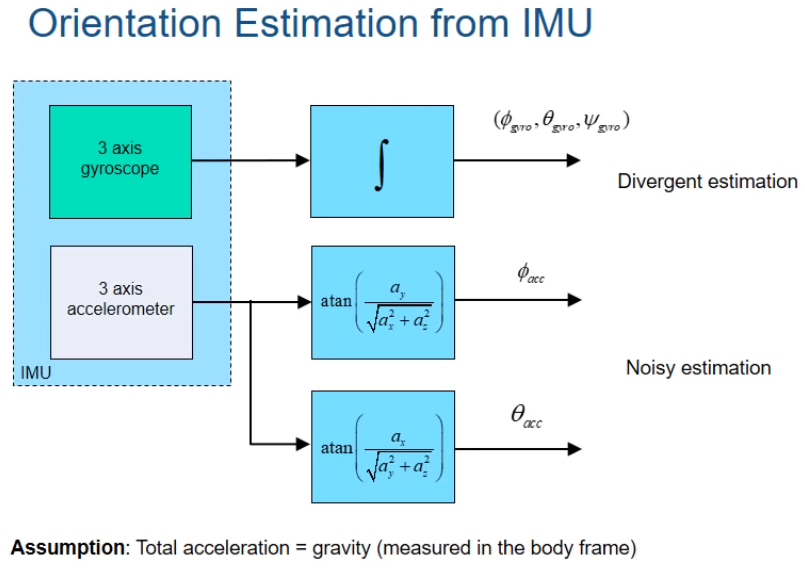

### Gyro integration

% Sampling frequency
dt = 1 / 512; % seconds

% Angular velocities are in deg/s

% Integrate wx to get angle of x axis
angle_x = zeros(size(wx));
for i = 2:length(wx)
    angle_x(i) = angle_x(i-1) + (wx(i) + wx(i-1))/2 * dt; 
end

% Integrate wy to get angle of y axis
angle_y = zeros(size(wy));
for i = 2:length(wy)
    angle_y(i) = angle_y(i-1) + (wy(i) + wy(i-1))/2 * dt; 
end

% Integrate wz to get angle of z axis
angle_z = zeros(size(wz));
for i = 2:length(wz)
    angle_z(i) = angle_z(i-1) + (wz(i) + wz(i-1))/2 * dt; 
end

### Angular accelerations based on Accelometer data

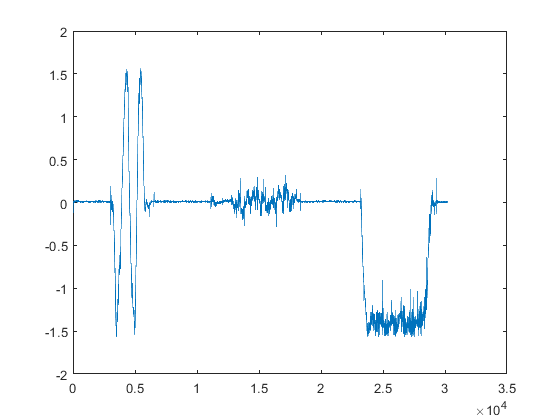

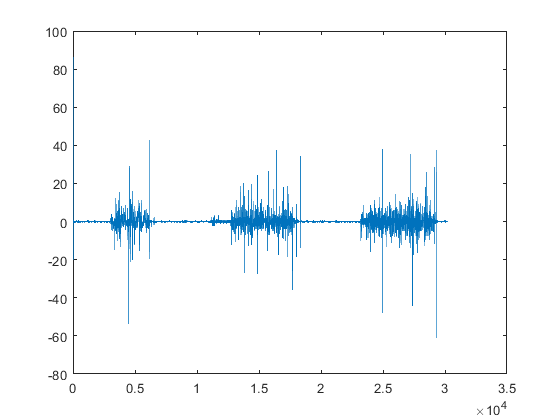

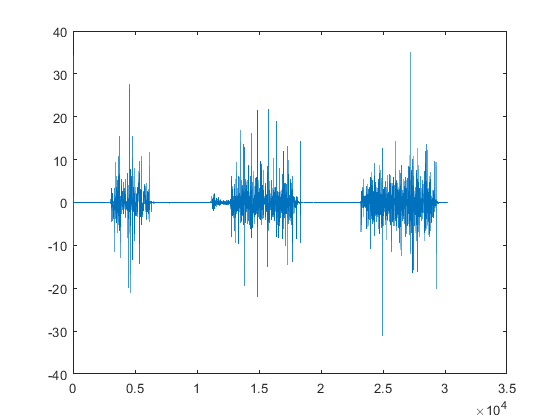

ang_acc_x = atan(ay./sqrt(ax.*ax + az.*az));
ang_acc_y = atan(ax./sqrt(ay.*ay + az.*az));